# `Clear Section`

clear
close all
clc

# `BPSK`

## Generate data bit stream

number_of_bits = 1000000                % number of transmitted bits

number_of_bits = 1000000

amplitude = 1                           % amp;itude of transmitted signal

amplitude = 1

bits = randi([0 1], 1, number_of_bits)  % generate random bits

bits =      0     1     1     1     1     0     1     1     1     0     1     1     1     1     0     0     0     0     1     1     0     0     1     1     0     0     1     1     0     1     0     0     0     0     0     0     1     1     1     1     0     1     0     0     0     0     0     0     0     1


Tx_Data = amplitude*(2*bits-1)          % converete to polar code

Tx_Data =     -1     1     1     1     1    -1     1     1     1    -1     1     1     1     1    -1    -1    -1    -1     1     1    -1    -1     1     1    -1    -1     1     1    -1     1    -1    -1    -1    -1    -1    -1     1     1     1     1    -1     1    -1    -1    -1    -1    -1    -1    -1     1


## Add AWGN from Channel

Eb = 1                                              % energy of bit

Eb = 1

SNR = -2:1:12                                       % SNR valus 

SNR =     -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12


No = Eb./(10.^(SNR/10))                             % variance value of noise

No =     1.5849    1.2589    1.0000    0.7943    0.6310    0.5012    0.3981    0.3162    0.2512    0.1995    0.1585    0.1259    0.1000    0.0794    0.0631


noise = (sqrt(No/2))'.*randn(1, number_of_bits)     % generate noise with zero mean and No/2 variance

noise =    -0.0845   -0.6328    0.5009   -0.0618    0.4463   -0.0985   -0.0174    1.0087   -0.6360   -0.1769   -0.3752    0.3024    0.7461    0.2978    1.3930   -0.4395   -0.2451    0.8981    0.3780    0.7772   -0.8443    1.5125    0.8865    0.4613   -0.9776    0.2474    0.7107   -1.1398   -1.2182    0.2056   -0.6355   -0.4624    0.9019   -0.3777   -1.5351    1.2104   -0.2195    0.6432   -0.5257    1.2670   -1.0216    0.3596   -1.0183    0.4082    0.8310    0.4314    0.7231    0.2579   -0.6640    0.3448
   -0.0753   -0.5640    0.4464   -0.0551    0.3977   -0.0877   -0.0155    0.8990   -0.5668   -0.1577   -0.3344    0.2695    0.6650    0.2654    1.2415   -0.3917   -0.2185    0.8005    0.3369    0.6927   -0.7525    1.3480    0.7901    0.4112   -0.8713    0.2205    0.6334   -1.0159   -1.0857    0.1832   -0.5664   -0.4121    0.8038   -0.3366   -1.3682    1.0788   -0.1957    0.5732   -0.4685    1.1292   -0.9105    0.3205   -0.9075    0.3638    0.7406    0.3845    0.6444    0.2299   -0.5918 

var(noise(1, :))

ans = 0.7943

## ِAdd Noise to Tx data

Rx_Data = Tx_Data + noise                           % adding noise to Tx data

Rx_Data =    -1.0845    0.3672    1.5009    0.9382    1.4463   -1.0985    0.9826    2.0087    0.3640   -1.1769    0.6248    1.3024    1.7461    1.2978    0.3930   -1.4395   -1.2451   -0.1019    1.3780    1.7772   -1.8443    0.5125    1.8865    1.4613   -1.9776   -0.7526    1.7107   -0.1398   -2.2182    1.2056   -1.6355   -1.4624   -0.0981   -1.3777   -2.5351    0.2104    0.7805    1.6432    0.4743    2.2670   -2.0216    1.3596   -2.0183   -0.5918   -0.1690   -0.5686   -0.2769   -0.7421   -1.6640    1.3448
   -1.0753    0.4360    1.4464    0.9449    1.3977   -1.0877    0.9845    1.8990    0.4332   -1.1577    0.6656    1.2695    1.6650    1.2654    0.2415   -1.3917   -1.2185   -0.1995    1.3369    1.6927   -1.7525    0.3480    1.7901    1.4112   -1.8713   -0.7795    1.6334   -0.0159   -2.0857    1.1832   -1.5664   -1.4121   -0.1962   -1.3366   -2.3682    0.0788    0.8043    1.5732    0.5315    2.1292   -1.9105    1.3205   -1.9075   -0.6362   -0.2594   -0.6155   -0.3556   -0.7701   -1.591

## BER Calculations

BER_Calculated = zeros(1, length(SNR));
BER_Theoretical = 0.5*erfc(sqrt(Eb./No))

BER_Theoretical =     0.1306    0.1038    0.0786    0.0563    0.0375    0.0229    0.0125    0.0060    0.0024    0.0008    0.0002    0.0000    0.0000    0.0000    0.0000


for i = 1 : length(SNR)
    BER_Calculated(1, i) = (sum(sign(Rx_Data(i, :)) ~= Tx_Data))/number_of_bits;
end
BER_Calculated

BER_Calculated =     0.1307    0.1038    0.0788    0.0565    0.0376    0.0230    0.0127    0.0060    0.0024    0.0008    0.0002    0.0000    0.0000         0         0


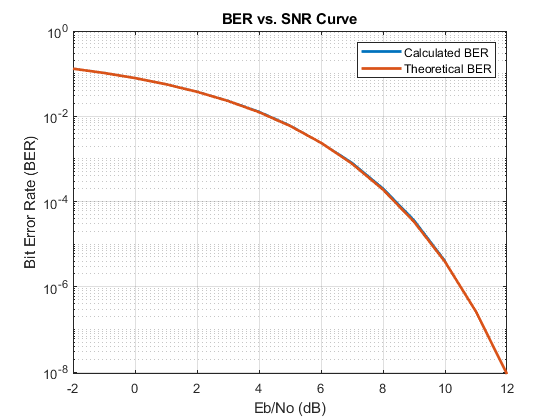

%subplot(2, 1, 1)
semilogy(SNR, BER_Calculated, 'LineWidth', 2)
xlim([-2 12])
hold on
semilogy(SNR, BER_Theoretical, 'LineWidth', 2)
xlabel("Eb/No (dB)")
ylabel("Bit Error Rate (BER)")
title("BER vs. SNR Curve")
legend("Calculated BER", "Theoretical BER")
grid on
hold off

# `QPSK`

## Generate data bit stream

number_of_bits = 1000000                  % number of transmitted bits

number_of_bits = 1000000

amplitude = 1                           % amp;itude of transmitted signal

amplitude = 1

bits = randi([0 1], 1, number_of_bits)  % generate random bits

bits =      1     0     1     1     0     1     0     1     1     1     1     0     1     1     0     0     0     1     0     0     0     0     1     0     1     0     1     0     0     0     0     0     0     1     1     0     1     0     1     0     0     1     1     0     0     0     1     1     0     1


Data = amplitude*(2*bits-1)             % converete to polar code

Data =      1    -1     1     1    -1     1    -1     1     1     1     1    -1     1     1    -1    -1    -1     1    -1    -1    -1    -1     1    -1     1    -1     1    -1    -1    -1    -1    -1    -1     1     1    -1     1    -1     1    -1    -1     1     1    -1    -1    -1     1     1    -1     1


real_part = Data(1, 1:2:end)            % get real part

real_part =      1     1    -1    -1     1     1     1    -1    -1    -1    -1     1     1     1    -1    -1    -1     1     1     1    -1     1    -1     1    -1     1     1    -1     1     1     1    -1     1    -1    -1    -1     1    -1    -1     1     1     1     1    -1     1    -1     1     1     1    -1


imaginary = Data(1, 2:2:end)            % get imaginary part

imaginary =     -1     1     1     1     1    -1     1    -1     1    -1    -1    -1    -1    -1    -1    -1     1    -1    -1    -1     1    -1    -1     1     1     1     1    -1     1     1    -1     1     1     1    -1     1     1    -1    -1     1     1     1    -1    -1     1     1    -1    -1     1     1


Tx_Data = real_part+1j*imaginary        % determine Tx data

Tx_Data =    1.0000 - 1.0000i   1.0000 + 1.0000i  -1.0000 + 1.0000i  -1.0000 + 1.0000i   1.0000 + 1.0000i   1.0000 - 1.0000i   1.0000 + 1.0000i  -1.0000 - 1.0000i  -1.0000 + 1.0000i  -1.0000 - 1.0000i  -1.0000 - 1.0000i   1.0000 - 1.0000i   1.0000 - 1.0000i   1.0000 - 1.0000i  -1.0000 - 1.0000i  -1.0000 - 1.0000i  -1.0000 + 1.0000i   1.0000 - 1.0000i   1.0000 - 1.0000i   1.0000 - 1.0000i  -1.0000 + 1.0000i   1.0000 - 1.0000i  -1.0000 - 1.0000i   1.0000 + 1.0000i  -1.0000 + 1.0000i   1.0000 + 1.0000i   1.0000 + 1.0000i  -1.0000 - 1.0000i   1.0000 + 1.0000i   1.0000 + 1.0000i   1.0000 - 1.0000i  -1.0000 + 1.0000i   1.0000 + 1.0000i  -1.0000 + 1.0000i  -1.0000 - 1.0000i  -1.0000 + 1.0000i   1.0000 + 1.0000i  -1.0000 - 1.0000i  -1.0000 - 1.0000i   1.0000 + 1.0000i   1.0000 + 1.0000i   1.0000 + 1.0000i   1.0000 - 1.0000i  -1.0000 - 1.0000i   1.0000 + 1.0000i  -1.0000 + 1.0000i   1.0000 - 1.0000i   1.0000 - 1.0000i   1.0000 + 1.0000i  -1.0000 + 1.0000i


## Add AWGN from Channel

Eb = 1                                              % energy of bit

Eb = 1

SNR = -2:1:12                                       % SNR valus 

SNR =     -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12


No = Eb./(10.^(SNR/10))                             % variance value of noise

No =     1.5849    1.2589    1.0000    0.7943    0.6310    0.5012    0.3981    0.3162    0.2512    0.1995    0.1585    0.1259    0.1000    0.0794    0.0631


noise = (sqrt(No/2))'.*randn(1, number_of_bits/2) + 1j*(sqrt(No/2))'.*randn(1, number_of_bits/2)    % generate noise with zero mean and No/2 variance

noise =   -1.0246 - 0.6516i   0.4679 + 0.4301i  -0.5814 - 0.4672i   0.8104 + 0.4184i   0.7765 - 1.3197i  -0.7528 - 0.4208i  -0.2132 + 0.4973i  -0.0721 + 1.4856i   1.5134 + 0.3593i   1.9838 - 0.2872i  -0.8259 + 0.9867i  -0.7666 + 1.1261i   0.5593 - 0.2812i   1.2827 + 0.3505i   0.7042 + 1.3803i  -0.2856 - 0.3470i  -0.5031 + 1.0417i  -0.3192 + 1.1852i  -0.8857 + 0.9448i   0.1535 - 0.4788i  -1.4314 - 1.4499i  -1.2639 - 0.9728i   0.4022 + 2.5910i  -0.5879 - 0.3609i  -1.8804 + 0.2471i  -0.3525 + 1.5548i   0.8331 - 0.0547i  -1.5485 + 0.9707i  -0.1987 - 0.2176i  -1.1405 - 0.1388i  -0.1151 + 0.0606i  -0.5907 - 0.1515i   0.1990 - 0.6720i  -0.6847 + 0.6080i   0.5986 + 1.5330i  -0.0281 + 1.0901i  -1.1140 - 0.1928i  -0.2909 - 0.4171i   1.3381 - 0.7749i  -0.5551 + 0.9748i  -0.4545 - 0.0925i   0.2696 - 0.5299i   0.9526 - 0.4031i  -1.7604 + 0.5820i   0.7771 - 0.2648i  -0.4820 + 0.5939i  -2.0789 - 1.5237i  -1.1477 - 0.5968i   0.8065 - 0.9472i  -0.2476 + 0.7077i
  -0.9132 - 0.5807i   0.4170 + 0.3834i  -

## Add Noise to Tx data

Rx_Data = Tx_Data + noise                           % adding noise to Tx data

Rx_Data =   -0.0246 - 1.6516i   1.4679 + 1.4301i  -1.5814 + 0.5328i  -0.1896 + 1.4184i   1.7765 - 0.3197i   0.2472 - 1.4208i   0.7868 + 1.4973i  -1.0721 + 0.4856i   0.5134 + 1.3593i   0.9838 - 1.2872i  -1.8259 - 0.0133i   0.2334 + 0.1261i   1.5593 - 1.2812i   2.2827 - 0.6495i  -0.2958 + 0.3803i  -1.2856 - 1.3470i  -1.5031 + 2.0417i   0.6808 + 0.1852i   0.1143 - 0.0552i   1.1535 - 1.4788i  -2.4314 - 0.4499i  -0.2639 - 1.9728i  -0.5978 + 1.5910i   0.4121 + 0.6391i  -2.8804 + 1.2471i   0.6475 + 2.5548i   1.8331 + 0.9453i  -2.5485 - 0.0293i   0.8013 + 0.7824i  -0.1405 + 0.8612i   0.8849 - 0.9394i  -1.5907 + 0.8485i   1.1990 + 0.3280i  -1.6847 + 1.6080i  -0.4014 + 0.5330i  -1.0281 + 2.0901i  -0.1140 + 0.8072i  -1.2909 - 1.4171i   0.3381 - 1.7749i   0.4449 + 1.9748i   0.5455 + 0.9075i   1.2696 + 0.4701i   1.9526 - 1.4031i  -2.7604 - 0.4180i   1.7771 + 0.7352i  -1.4820 + 1.5939i  -1.0789 - 2.5237i  -0.1477 - 1.5968i   1.8065 + 0.0528i  -1.2476 + 1.7077i
   0.0868 - 1.5807i   1.4170 + 1.3834i 

## BER Calculations

BER_Calculated = zeros(1, length(SNR));
BER_Theoretical = 0.5*erfc(sqrt(Eb./No))

BER_Theoretical =     0.1306    0.1038    0.0786    0.0563    0.0375    0.0229    0.0125    0.0060    0.0024    0.0008    0.0002    0.0000    0.0000    0.0000    0.0000


R = real(Rx_Data)

R =    -0.0246    1.4679   -1.5814   -0.1896    1.7765    0.2472    0.7868   -1.0721    0.5134    0.9838   -1.8259    0.2334    1.5593    2.2827   -0.2958   -1.2856   -1.5031    0.6808    0.1143    1.1535   -2.4314   -0.2639   -0.5978    0.4121   -2.8804    0.6475    1.8331   -2.5485    0.8013   -0.1405    0.8849   -1.5907    1.1990   -1.6847   -0.4014   -1.0281   -0.1140   -1.2909    0.3381    0.4449    0.5455    1.2696    1.9526   -2.7604    1.7771   -1.4820   -1.0789   -0.1477    1.8065   -1.2476
    0.0868    1.4170   -1.5182   -0.2777    1.6921    0.3290    0.8100   -1.0643    0.3488    0.7681   -1.7361    0.3168    1.4984    2.1432   -0.3724   -1.2545   -1.4484    0.7155    0.2107    1.1368   -2.2758   -0.1265   -0.6415    0.4760   -2.6759    0.6858    1.7425   -2.3801    0.8229   -0.0164    0.8974   -1.5265    1.1774   -1.6103   -0.4665   -1.0251    0.0072   -1.2593    0.1926    0.5053    0.5949    1.2403    1.8490   -2.5689    1.6926   -1.4296   -0.8528   -0.0229    1.7188   -1

I = imag(Rx_Data)

I =    -1.6516    1.4301    0.5328    1.4184   -0.3197   -1.4208    1.4973    0.4856    1.3593   -1.2872   -0.0133    0.1261   -1.2812   -0.6495    0.3803   -1.3470    2.0417    0.1852   -0.0552   -1.4788   -0.4499   -1.9728    1.5910    0.6391    1.2471    2.5548    0.9453   -0.0293    0.7824    0.8612   -0.9394    0.8485    0.3280    1.6080    0.5330    2.0901    0.8072   -1.4171   -1.7749    1.9748    0.9075    0.4701   -1.4031   -0.4180    0.7352    1.5939   -2.5237   -1.5968    0.0528    1.7077
   -1.5807    1.3834    0.5836    1.3729   -0.1762   -1.3750    1.4432    0.3240    1.3202   -1.2559   -0.1206    0.0036   -1.2506   -0.6876    0.2302   -1.3093    1.9284    0.0563   -0.1579   -1.4268   -0.2922   -1.8670    1.3093    0.6783    1.2202    2.3857    0.9512   -0.1348    0.8060    0.8763   -0.9460    0.8650    0.4011    1.5419    0.3663    1.9715    0.8282   -1.3717   -1.6906    1.8688    0.9175    0.5277   -1.3593   -0.4813    0.7640    1.5294   -2.3580   -1.5319    0.1558    1

extract_Data(1:size(R, 1), 1:2:2*size(R, 2)) = R

extract_Data =    -0.0246         0    1.4679         0   -1.5814         0   -0.1896         0    1.7765         0    0.2472         0    0.7868         0   -1.0721         0    0.5134         0    0.9838         0   -1.8259         0    0.2334         0    1.5593         0    2.2827         0   -0.2958         0   -1.2856         0   -1.5031         0    0.6808         0    0.1143         0    1.1535         0   -2.4314         0   -0.2639         0   -0.5978         0    0.4121         0   -2.8804         0
    0.0868         0    1.4170         0   -1.5182         0   -0.2777         0    1.6921         0    0.3290         0    0.8100         0   -1.0643         0    0.3488         0    0.7681         0   -1.7361         0    0.3168         0    1.4984         0    2.1432         0   -0.3724         0   -1.2545         0   -1.4484         0    0.7155         0    0.2107         0    1.1368         0   -2.2758         0   -0.1265         0   -0.6415         0    0.4760         0   -

extract_Data(1:size(I, 1), 2:2:2*size(I, 2)) = I

extract_Data =    -0.0246   -1.6516    1.4679    1.4301   -1.5814    0.5328   -0.1896    1.4184    1.7765   -0.3197    0.2472   -1.4208    0.7868    1.4973   -1.0721    0.4856    0.5134    1.3593    0.9838   -1.2872   -1.8259   -0.0133    0.2334    0.1261    1.5593   -1.2812    2.2827   -0.6495   -0.2958    0.3803   -1.2856   -1.3470   -1.5031    2.0417    0.6808    0.1852    0.1143   -0.0552    1.1535   -1.4788   -2.4314   -0.4499   -0.2639   -1.9728   -0.5978    1.5910    0.4121    0.6391   -2.8804    1.2471
    0.0868   -1.5807    1.4170    1.3834   -1.5182    0.5836   -0.2777    1.3729    1.6921   -0.1762    0.3290   -1.3750    0.8100    1.4432   -1.0643    0.3240    0.3488    1.3202    0.7681   -1.2559   -1.7361   -0.1206    0.3168    0.0036    1.4984   -1.2506    2.1432   -0.6876   -0.3724    0.2302   -1.2545   -1.3093   -1.4484    1.9284    0.7155    0.0563    0.2107   -0.1579    1.1368   -1.4268   -2.2758   -0.2922   -0.1265   -1.8670   -0.6415    1.3093    0.4760    0.6783   -

for i = 1 : length(SNR)
    BER_Calculated(1, i) = (sum(sign(extract_Data(i, :)) ~= Data))/number_of_bits;
end
BER_Calculated

BER_Calculated =     0.1306    0.1036    0.0786    0.0564    0.0377    0.0228    0.0125    0.0060    0.0025    0.0008    0.0002    0.0000    0.0000         0         0


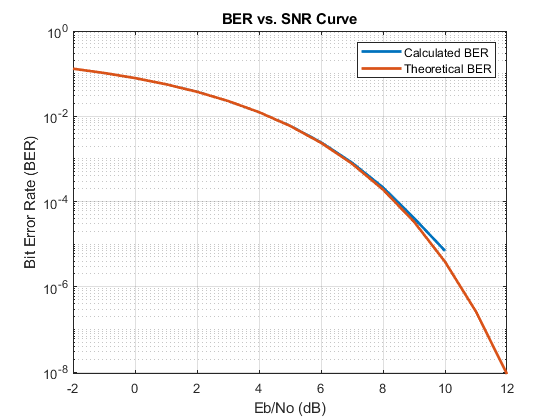

%subplot(2, 1, 1)
semilogy(SNR, BER_Calculated, 'LineWidth', 2)
xlim([-2 12])
hold on
semilogy(SNR, BER_Theoretical, 'LineWidth', 2)
xlabel("Eb/No (dB)")
ylabel("Bit Error Rate (BER)")
title("BER vs. SNR Curve")
legend("Calculated BER", "Theoretical BER")
grid on